## Vectorization, or how to avoid for loops 

Parts copied from Matlab documentation

n = 10000;
a = zeros(n,1);

tic
for i = 1:n
    a(i) = a(i) + 1;
end
toc

Elapsed time is 1.896493 seconds.


tic
a = a + 1;
toc

Elapsed time is 0.033738 seconds.


tic
i = 0;
for t = 0:.001:10
    i = i + 1;
    y(i) = sin(t);
end
toc

Elapsed time is 2.830177 seconds.


tic
t = 0:.001:10;
y = sin(t);
toc

Elapsed time is 0.032483 seconds.


write your own functions to operate like that too

## Array Operations

radius  = rand(10000,1); 
area = zeros(size(radius));
tic
for i = 1:length(radius)
    area(i) = pi * radius(i)^2;
end
toc

Elapsed time is 1.885653 seconds.



tic
area = pi * radius.^2;
toc

Elapsed time is 0.020468 seconds.


**Logical Array Operations**

A logical extension of the bulk processing of arrays is to vectorize comparisons and decision making. MATLAB comparison operators accept vector inputs and return vector outputs.

radius > 0.5

ans =    1
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   1
   1
   0
   1
   1
   0
   1
   1
   0
   1
   0
   0
   1
   1
   0
   0
   1
   1
   1
   0
   0
   0
   1
   1
   1
   0
   1
   0
   0
   1
   1
   0
   0
   0
   1
   1
   1
   1
   0
   1
   1
   0
   0
   1
   1
   0
   0
   0
   1
   0
   1
   0
   1
   0
   0
   0
   0
   1
   0
   1
   1
   1
   1
   0
   0
   1
   1
   1
   1
   0
   1
   1
   1
   0
   0
   1
   1
   0
   1
   0
   1
   1
   1
   1
   1
   0
   1
   0
   0
   1
   0
   1
   1
   0
   1
   0
   1
   0
   0
   1
   0
   1
   0
   0
   1
   0
   1
   1
   1
   1
   0
   0
   0
   0
   1
   0
   1
   0
   0
   0
   1
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   1
   0
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   0
   0
   0
   1
   1
   0
   1
   0
   0
   1
   1
   0
   0
   0
   1
   0
   1
   0
   1
   1
   0
   1
   0
   1
   1
   0
   0
   1
   0
   1
   0
   0
   1
   0
   1
   0
   0
   1
   1
   1
   0
   1
   0
   1

Logical arrays can bypass the need to construct an index-vector

ind = find(radius>0.5)

ind =      1
     8
    12
    13
    15
    16
    18
    19
    21
    24


radius_large = radius( ind );
radius_large = radius(radius > 0.5);

MATLAB allows you to perform a logical AND or OR on the elements of an entire vector with the functions all and any, respectively. You can throw a warning if all values of D are below zero:

if all(radius > 0.5)
   warning('There are only large radii.')
   return
end

MATLAB can compare two vectors of the same size, allowing you to impose further restrictions. 

radius((radius > 0.5) & (area < 1.5))

ans =     0.5642
    0.6180
    0.5640
    0.6393
    0.6654
    0.5267
    0.6804
    0.5325
    0.6798
    0.5174


The resulting vector is the same size as the inputs.

To aid comparison, MATLAB contains special values to denote overflow, underflow, and undefined operators, such as inf and nan. Logical operators isinf and isnan exist to help perform logical tests for these special values. For example, it is often useful to exclude NaN values from computations:

x = [2 -1 0 3 NaN 2 NaN 11 4 Inf];
xvalid = x(~isnan(x))

xvalid =      2    -1     0     3     2    11     4   Inf


Note:   Inf == Inf returns true; however, NaN == NaN always returns false.

## Matrix Operations

Matrix operations act according to the rules of linear algebra. These operations are most useful in vectorization if you are working with multidimensional data.

Suppose you want to evaluate a function, F, of two variables, x and y, F(x,y) = exp(-x^2 - y^2)

To evaluate this function at every combination of points in the x and y, you need to define a grid of values:

x = linspace(-10,10,100);
y = linspace(-10,10,100);
v = [0.5 0.5];
im = zeros(length(x),length(y));
f = @(x,y) sin( x * v(1) + y*v(2) );
tic
for i = 1:length(x)
    for j = 1:length(y)
        im(j,i) = f(x(i),y(j));        
    end
end
toc

Elapsed time is 1.786977 seconds.


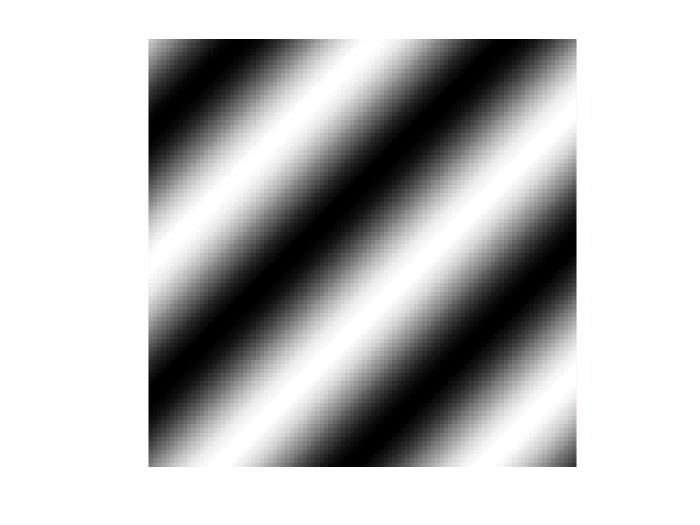

imagesc(im);
axis image off

colormap gray

This can also be done with meshgrid

[X,Y] = meshgrid(1:4,11:13)

X =      1     2     3     4
     1     2     3     4
     1     2     3     4


Y =     11    11    11    11
    12    12    12    12
    13    13    13    13


tic
[X,Y] = meshgrid(x,y);
im = f(X,Y);
toc

Elapsed time is 0.048302 seconds.


imagesc(im);
axis image off

colormap gray

Without meshgrid, you might need to write two for loops to iterate through vector combinations. The function ndgrid also creates number grids from vectors, but can construct grids beyond three dimensions. meshgrid can only construct 2-D and 3-D grids.

In some cases, using matrix multiplication eliminates intermediate steps needed to create number grids:

x = -2:2;
y = -1:0.5:1;
x'*y

ans =     2.0000    1.0000         0   -1.0000   -2.0000
    1.0000    0.5000         0   -0.5000   -1.0000
         0         0         0         0         0
   -1.0000   -0.5000         0    0.5000    1.0000
   -2.0000   -1.0000         0    1.0000    2.0000


## Constructing Matrices

When vectorizing code, you often need to construct a matrix with a particular size or structure. Techniques exist for creating uniform matrices. For instance, you might need a 5-by-5 matrix of equal elements:

A = ones(5,5)*10;

Or, you might need a matrix of repeating values:

v = 1:5;
A = repmat(v,3,1)

A =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


The function repmat possesses flexibility in building matrices from smaller matrices or vectors. repmat creates matrices by repeating an input matrix:

A = repmat(1:3,5,2)

A =      1     2     3     1     2     3
     1     2     3     1     2     3
     1     2     3     1     2     3
     1     2     3     1     2     3
     1     2     3     1     2     3


B = repmat([1 2; 3 4],2,2)

B =      1     2     1     2
     3     4     3     4
     1     2     1     2
     3     4     3     4


The bsxfun function provides a way of combining matrices of different dimensions. Suppose that matrix A represents test scores, the rows of which denote different classes. You want to calculate the difference between the average score and individual scores for each class. Your first thought might be to compute the simple difference, A - mean(A). However, MATLAB throws an error if you try this code because the matrices are not the same size. Instead, bsxfun performs the operation without explicitly reconstructing the input matrices so that they are the same size.

A = [97 89 84; 95 82 92; 64 80 99;76 77 67;...
 88 59 74; 78 66 87; 55 93 85]

A =     97    89    84
    95    82    92
    64    80    99
    76    77    67
    88    59    74
    78    66    87
    55    93    85


dev = bsxfun(@minus,A,mean(A))

dev =     18    11     0
    16     4     8
   -15     2    15
    -3    -1   -17
     9   -19   -10
    -1   -12     3
   -24    15     1
